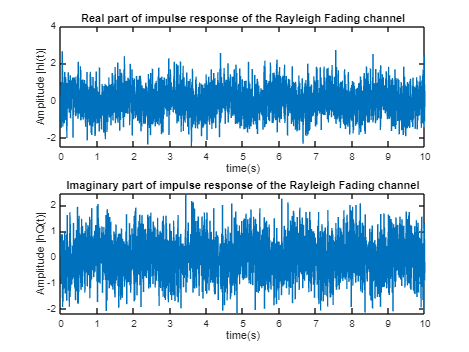

% MATLAB function to generate Rayleigh Fading samples based on Clarke’s model
function [h] = rayleighFading(M, N, fd, Ts)
    % M = number of multi-paths in the channel
    % N = number of samples to generate
    % fd = maximum Doppler frequency
    % Ts = sampling period

    a = 0;
    b = 2 * pi;
    
    % Generate uniformly distributed random phases
    alpha = a + (b - a) * rand(1, M); 
    beta = a + (b - a) * rand(1, M); 
    theta = a + (b - a) * rand(1, M); 
    
    m = 1:M;  % Indices for multipaths
    
    for n = 1:N
        % Generate real and imaginary parts of Rayleigh fading
        x = cos(((2 .* m - 1) * pi + theta) / (4 * M));
        h_re(n) = 1 / sqrt(M) * sum(cos(2 * pi * fd * x * n' * Ts + alpha));
        h_im(n) = 1 / sqrt(M) * sum(sin(2 * pi * fd * x * n' * Ts + beta));
    end
    
    h = h_re + 1i * h_im;  % Complex Rayleigh fading envelope
end

% Test program to generate Rayleigh fading samples using Clarke's model
clc; clear;

M = 15;         % Number of multipaths
N = 10^5;       % Number of samples to generate
fd = 100;       % Maximum Doppler frequency (Hz)
Ts = 0.0001;    % Sampling period in seconds

% Generate Rayleigh fading samples
h = rayleighFading(M, N, fd, Ts);
h_re = real(h);   % Real part of the channel
h_im = imag(h);   % Imaginary part of the channel

% Plot real and imaginary parts
figure;
subplot(2,1,1);
plot([0:N-1] * Ts, h_re);
title('Real part of impulse response of the Rayleigh Fading channel');
xlabel('time(s)');
ylabel('Amplitude |hI(t)|');

subplot(2,1,2);
plot([0:N-1] * Ts, h_im);
title('Imaginary part of impulse response of the Rayleigh Fading channel');
xlabel('time(s)');
ylabel('Amplitude |hQ(t)|');

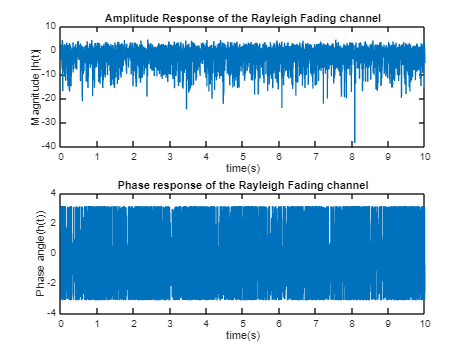


% Plot magnitude and phase
figure;
subplot(2,1,1);
plot([0:N-1] * Ts, 10 * log10(abs(h)));
title('Amplitude Response of the Rayleigh Fading channel');
xlabel('time(s)');
ylabel('Magnitude |h(t)|');

subplot(2,1,2);
plot([0:N-1] * Ts, angle(h));
title('Phase response of the Rayleigh Fading channel');
xlabel('time(s)');
ylabel('Phase angle(h(t))');


%Statistical properties
mean_re=mean(h_re)

mean_re = 0.0020

mean_im=mean(h_im)

mean_im = -0.0023

var_re=var(h_re)

var_re = 0.5019

var_im=var(h_im)

var_im = 0.5025

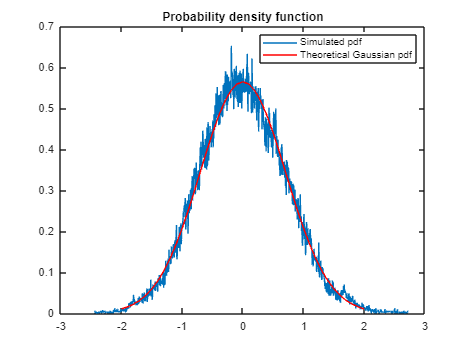

%comparing the PDF of real part of generated samples against the PDF of Gaussian distribution
[val,bin]=hist(h_re,1000); % pdf of real part of generated Raleigh Fading Samples
figure;
plot(bin,val/trapz(bin,val)); %Normalizing the PDF to match theoretical result
%Trapz function gives the total area under the PDF curve. It is used as the normalization factor
hold on;
x=-2:0.1:2;
y=normpdf(x,0,sqrt(0.5)); % theoretical gaussian pdf
plot(x,y,'r');
title('Probability density function');
legend('Simulated pdf','Theoretical Gaussian pdf');

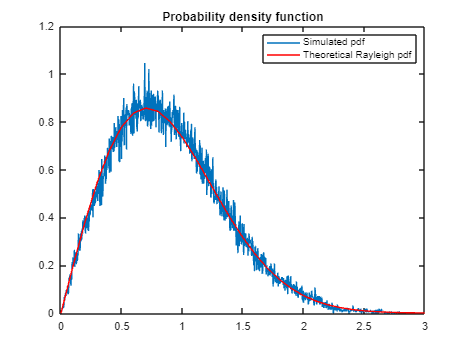

figure;
%comparing the PDF of overal response of the channel against the PDF of Rayleigh distribution
[val,bin]=hist(abs(h),1000); % pdf of generated Raleigh Fading samples
plot(bin,val/trapz(bin,val)); %Normalizing the PDF to match theoretical result
%Trapz function gives the total area under the PDF curve. It is used as the normalization factor
hold on;
z=0:0.1:3; sigma=1;
y=2*z/(sigma^2).*exp(-z.^2/(sigma^2)); % theoretical Raleigh pdf
plot(z,y,'r');
title('Probability density function');
legend('Simulated pdf','Theoretical Rayleigh pdf');